# Part 2: Training an Autoencoder

***Industrial Machinery Anomaly Detection***

# 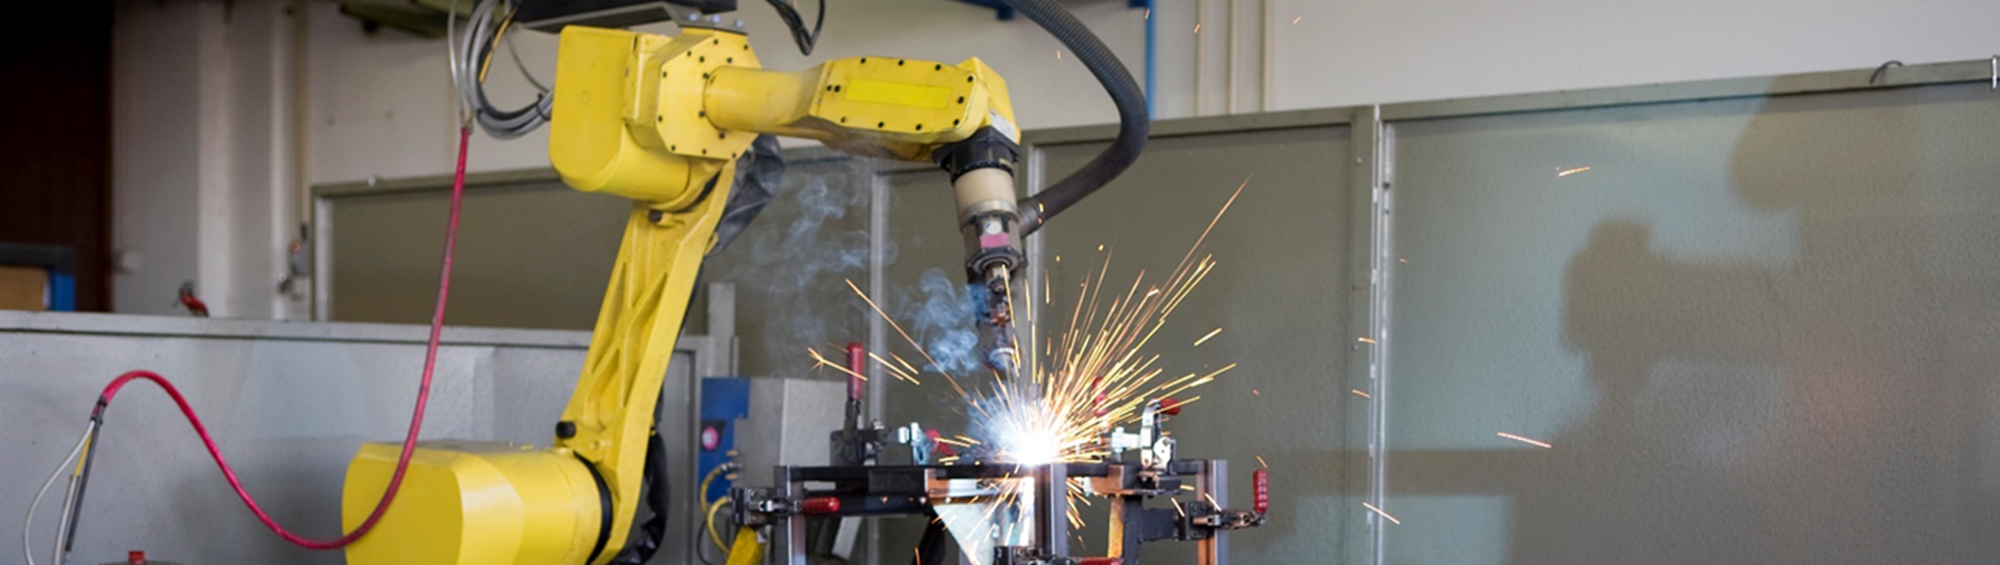

Here is an example where a Deep Learning Autoencoder is trained to detect if a machine metal cutter is working normally or abnormally. It is trained on a set of 12 features, extracted from historical accelerometer data from "normal" operation, which was the time directly after a scheduled maintenance period. Features include mean, standard deviation, kurtosis, crest factor, and were computed from raw data using the [Diagnostic Feature Designer App](https://www.mathworks.com/help/predmaint/gs/explore-features-in-diagnostic-feature-designer.html) from the [Predictive Maintenance Toolbox](https://www.mathworks.com/products/predictive-maintenance.html).

This trained model is then used to monitor the machine over time. At a certain point the model output differs and drifts from the sensor data output. The more drift, the larger the amount of anomalies are detected which is an indication the machine is acting abnormal.

## **Load Features and Labels**

In the previous section, we extracted highly ranked features from our data.

The data has two labeled states: **Before** & **After**. These refer to data collected before and after maintenance. We will assume that the data collected **after **maintenance represents a normal (healthy) operating state. We may not be able to say the same for the **before **data -- because we were performing scheduled maintenance, this data may be either normal or abnormal. 

load("FeatureEntire.mat")

head(featureAll)

ans = 8×13 table
    label     ch1_stats/Col1_CrestFactor    ch1_stats/Col1_Kurtosis    ch1_stats/Col1_RMS    ch1_stats/Col1_Std    ch2_stats/Col1_Mean    ch2_stats/Col1_RMS    ch2_stats/Col1_Skewness    ch2_stats/Col1_Std    ch3_stats/Col1_CrestFactor    ch3_stats/Col1_SINAD    ch3_stats/Col1_SNR    ch3_stats/Col1_THD
    ______    __________________________    _______________________    __________________    __________________    ___________________    __________________    _______________________    __________________    __________________________    ____________________    

## **Split into Training and Validation Datasets**

rng(0) % set for reproducibility

idx = cvpartition(featureAll.label, 'holdout', 0.1);
featureTrain = featureAll(idx.training, :);
featureVal = featureAll(idx.test, :);

## **Train Model**

The model is going to be trained on data **After** maintenance. This is the time when the machine is running "normally".

X = extractLabeledData(featureTrain, ...
    "Label", "After");

featureDimension = 1;

% Define biLSTM network layers
layers = [ sequenceInputLayer(featureDimension, 'Name', 'in')
    bilstmLayer(16, 'Name', 'bilstm1')
    reluLayer('Name', 'relu1')
    bilstmLayer(32, 'Name', 'bilstm2')
    reluLayer('Name', 'relu2')
    bilstmLayer(16, 'Name', 'bilstm3')
    reluLayer('Name', 'relu3')
    fullyConnectedLayer(featureDimension, 'Name', 'fc')
    regressionLayer('Name', 'out') ];

% Set Training Options
options = trainingOptions('adam', ...
    'Plots', 'training-progress', ...
    'MiniBatchSize', 500,...
    'MaxEpochs',500);

doTraining = false; % Select if you would like the model to train or use the pretrained model on file
if doTraining
    net = trainNetwork(X, X, layers, options);
else
    load("TrainedModel")
end

## **Visualize Model Behavior on Validation Data**

Extract and visualize a sample from Before and After maintenance

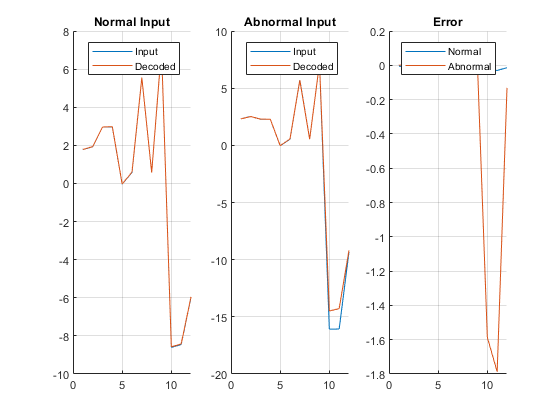

testAfter = {featureVal(1200, 2:end).Variables}; % 1200 is a sample from After
testBefore = {featureVal(200, 2:end).Variables}; % 200 is a sample from Before

% Predict decoded signal for both
decodedAfter = predict(net,testAfter);
decodedBefore = predict(net,testBefore);

% Visualize
visualizeModelBehavior(testAfter, testBefore, decodedAfter, decodedBefore)

## **Visualize Model Error on Validation Data**

Extract data **Before** and **After **maintenance

% Extract data Before maintenance
XValBefore = extractLabeledData(featureVal, ...
    "Label", "Before");

% Predict output before maintenance and calculate error
yHatBefore = predict(net, XValBefore);
errorBefore = calculateError(XValBefore, yHatBefore);

% Extract data after maintenance
XValAfter = extractLabeledData(featureVal, ...
    "Label", "After");

% Predict output after maintenance and calculate error
yHatAfter = predict(net, XValAfter);
errorAfter = calculateError(XValAfter, yHatAfter);

Plot results

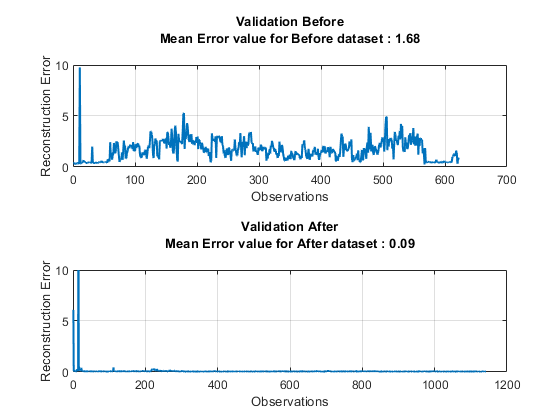

visualizeValidationError(errorBefore, errorAfter);

## **Anomaly Detection**

Calculate error on full validation data

XValAll = extractLabeledData(featureVal, ...
    "Label", "All");

yHatAll = predict(net, XValAll);
errorAll = calculateError(XValAll, yHatAll);

Define an anomaly as a point which has reconstruction error 0.5 times larger than the mean across all observations.

This threshold was determined through a tuning process, which can be adjusted using the numeric slider below.

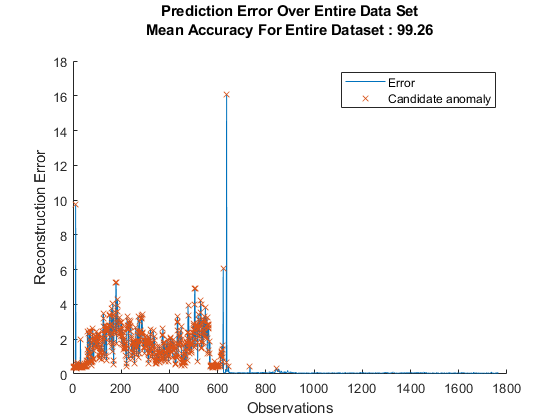

thresh = 0.5;
anomalies = errorAll > thresh*mean(errorAll);

visualizeAnomalies(anomalies, errorAll, featureVal);

**Helper Functions**

**Calculate Error**

function E = calculateError(X, Y)

E = zeros(length(X),1);
for i = 1:length(X)
    E(i,:) = sqrt(sum((Y{i} - X{i}).^2));
end

end

**Visualize Validation Error**

function visualizeValidationError(errorBefore, errorAfter)
figure("Color", "W")
tiledlayout("flow")

nexttile
plot(1:length(errorBefore), errorBefore, 'LineWidth',1.5), grid on
title(["Validation Before", ...
    sprintf("Mean Error value for Before dataset : %.2f\n", mean(errorBefore))])
xlabel("Observations")
ylabel("Reconstruction Error")
ylim([0 10])

nexttile
plot(1:length(errorAfter), errorAfter, 'LineWidth',1.5), grid on,
title(["Validation After", ...
    sprintf("Mean Error value for After dataset : %.2f\n", mean(errorAfter))])
xlabel("Observations")
ylabel("Reconstruction Error")
ylim([0 10])
end

**Visualize Anomalies**

function visualizeAnomalies(anomalies, errorAll, featureVal)
anomalyIdx = find(anomalies);
anomalyErr = errorAll(anomalies);

predAE = categorical(anomalies, [1, 0], {'Before', 'After'})';
acc = numel(find(featureVal.label == transpose(predAE)))/length(predAE)*100;

figure("Color", "W");
hold on
plot(errorAll)
plot(anomalyIdx, anomalyErr, 'x')
hold off
title(["Prediction Error Over Entire Data Set", ...
    sprintf('Mean Accuracy For Entire Dataset : %.2f\n', mean(acc))])
ylabel('Reconstruction Error')
xlabel('Observations')
legend( "Error", "Candidate anomaly" )
end

**Visualize Model Behavior**

function visualizeModelBehavior(normalData, abnormalData, decodedNorm, decodedAbNorm)
%visualizeModelBehavior Visualize model behavior on sample validation data

arguments
    normalData(1,1) cell
    abnormalData(1,1) cell
    decodedNorm(1,1) cell
    decodedAbNorm(1,1) cell
end

figure("Color", "W")
tiledlayout(1,3)

nexttile()
hold on
plot(normalData{:})
plot(decodedNorm{:})
hold off
title('Normal Input')
legend({'Input', 'Decoded'}), grid on

nexttile()
hold on
plot(abnormalData{:})
plot(decodedAbNorm{:})
hold off
title('Abnormal Input')
legend({'Input', 'Decoded'}), grid on

nexttile()
hold on
plot(normalData{:} - decodedNorm{:})
plot(abnormalData{:} - decodedAbNorm{:})
hold off
title('Error')
legend({'Normal', 'Abnormal'}), grid on

end

Copyright 2021 The MathWorks, Inc.